% Initialization
close all
clear
clc

% Symbolic variables
syms x y t real

% Parameters
gamma=7/5; mu=1; epsilon=1; sigma=0; q=-1; m=1; qi=+1; mi=1; ri=1;

% Spatial coordinates
X=[x,y];

% Analytical solution
r=1+x^2*y^2*t

$$r = t\,x^{2}\,y^{2}+1$$

w=[+r*x*t
   -r*y*t]

$$w = \left[\begin{array}{c} t\,x\,\left(t\,x^{2}\,y^{2}+1\right)\\ -t\,y\,\left(t\,x^{2}\,y^{2}+1\right) \end{array}\right]$$

g=1+x^2*y^2*t

$$g = t\,x^{2}\,y^{2}+1$$

H=(2*x^2+3*y^2)*x^2*y*t^2

$$H = t^{2}\,x^{2}\,y\,\left(2\,x^{2}+3\,y^{2}\right)$$

E=[+2*x^4*y^2*t
   -2*x^3*y^3*t]

$$E = \left[\begin{array}{c} 2\,t\,x^{4}\,y^{2}\\ -2\,t\,x^{3}\,y^{3} \end{array}\right]$$


% Rhs terms
f_r=x^2*y^2-t*(t*x^2*y^2+1)

$$f\_r = x^{2}\,y^{2}-t\,\left(t\,x^{2}\,y^{2}+1\right)$$

f_w=[x*(t*x^2*y^2+1)+t*x^3*y^2-(2*t^2*x*(t*x^2*y^2+1))/5+2*t*x^4*y^2*(t*x^2*y^2+1)-(2*t*x*y^2*(t^2*x^2+t^2*y^2-2))/5-t^3*x^2*y^2*(2*x^2+3*y^2)*(t*x^2*y^2+1)
    (8*t^2*y)/5-y+(4*t*x^2*y)/5-2*t*x^2*y^3-(2*t^3*x^4*y)/5+(6*t^3*x^2*y^3)/5-2*t*x^3*y^3*(t*x^2*y^2+1)-t^3*x^3*y*(2*x^2+3*y^2)*(t*x^2*y^2+1)]

$$f\_w = \left[\begin{array}{c} x\,\left(t\,x^{2}\,y^{2}+1\right)+t\,x^{3}\,y^{2}-\frac{2\,t^{2}\,x\,\left(t\,x^{2}\,y^{2}+1\right)}{5}+2\,t\,x^{4}\,y^{2}\,\left(t\,x^{2}\,y^{2}+1\right)-\frac{2\,t\,x\,y^{2}\,\left(t^{2}\,x^{2}+t^{2}\,y^{2}-2\right)}{5}-t^{3}\,x^{2}\,y^{2}\,\left(2\,x^{2}+3\,y^{2}\right)\,\left(t\,x^{2}\,y^{2}+1\right)\\ \frac{8\,t^{2}\,y}{5}-y+\frac{4\,t\,x^{2}\,y}{5}-2\,t\,x^{2}\,y^{3}-\frac{2\,t^{3}\,x^{4}\,y}{5}+\frac{6\,t^{3}\,x^{2}\,y^{3}}{5}-2\,t\,x^{3}\,y^{3}\,\left(t\,x^{2}\,y^{2}+1\right)-t^{3}\,x^{3}\,y\,\left(2\,x^{2}+3\,y^{2}\right)\,\left(t\,x^{2}\,y^{2}+1\right) \end{array}\right]$$

f_g=(3*t^3*y^2)/5-(t^3*x^2)/5-(7*t)/5+x^2*y^2-(7*t^2*x^2*y^2)/5+(3*t^4*x^2*y^4)/5-(t^4*x^4*y^2)/5+2*t^2*x^3*y^4*(t*x^2*y^2+1)+2*t^2*x^5*y^2*(t*x^2*y^2+1)

$$f\_g = \frac{3\,t^{3}\,y^{2}}{5}-\frac{t^{3}\,x^{2}}{5}-\frac{7\,t}{5}+x^{2}\,y^{2}-\frac{7\,t^{2}\,x^{2}\,y^{2}}{5}+\frac{3\,t^{4}\,x^{2}\,y^{4}}{5}-\frac{t^{4}\,x^{4}\,y^{2}}{5}+2\,t^{2}\,x^{3}\,y^{4}\,\left(t\,x^{2}\,y^{2}+1\right)+2\,t^{2}\,x^{5}\,y^{2}\,\left(t\,x^{2}\,y^{2}+1\right)$$

j=[4*t^2*x^4-2*x^4*y^2+t*x*(t*x^2*y^2+1)+12*t^2*x^2*y^2
   2*x^3*y^3-t*y*(t*x^2*y^2+1)-6*t^2*x*y^3-8*t^2*x^3*y]

$$j = \left[\begin{array}{c} 4\,t^{2}\,x^{4}-2\,x^{4}\,y^{2}+t\,x\,\left(t\,x^{2}\,y^{2}+1\right)+12\,t^{2}\,x^{2}\,y^{2}\\ 2\,x^{3}\,y^{3}-t\,y\,\left(t\,x^{2}\,y^{2}+1\right)-6\,t^{2}\,x\,y^{3}-8\,t^{2}\,x^{3}\,y \end{array}\right]$$

f_G=x^2*y^2*t

$$f\_G = t\,x^{2}\,y^{2}$$


% Equations of state for pressure
p=simplify((gamma-1)*(g-1/2*(w'*w)/r),'Steps',100)

$$p = -\frac{\left(t\,x^{2}\,y^{2}+1\right)\,\left(t^{2}\,x^{2}+t^{2}\,y^{2}-2\right)}{5}$$

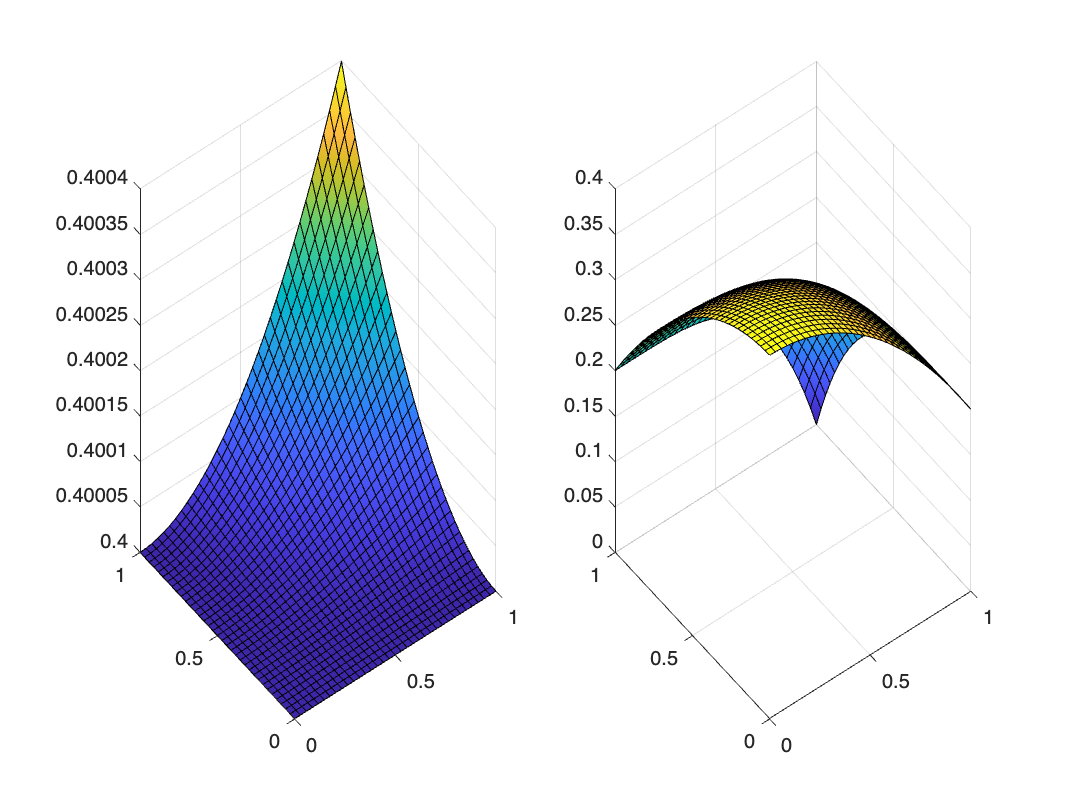


% Plot pressure
subplot(1,2,1); fsurf(@(x,y) eval(subs(p,t,1e-3)),[0,1,0,1]);
subplot(1,2,2); fsurf(@(x,y) eval(subs(p,t,1.00)),[0,1,0,1]);


% Cross product
w_H=cross([w;0],[0;0;H]);
w_H=w_H(1:2);

% Check residual of density
R_r=simplify(...
    diff(r,t)...
    +mydivergence(w,X)...
    +1/y*w(2)...
    -f_r,...
    'Steps',100)

$$R\_r = 0$$


% Check residual of momentum
R_w=simplify(...
    diff(w,t)...
    +mydivergence(w*w'/r,X)...
    +mygradient(p,X)'...
    +[1/y*w(1)*w(2)/r;1/y*w(2)*w(2)/r]...
    -q/m*r*E...
    -q/m*mu*w_H...
    -f_w,...
    'Steps',100)

$$R\_w = \left[\begin{array}{c} 0\\ 0 \end{array}\right]$$


% Check residual of energy
R_g=simplify(...
    diff(g,t)...
    +mydivergence((g+p)*w/r,X)...
    +1/y*(g+p)*w(2)/r...
    -q/m*(w'*E)...
    -f_g,...
    'Steps',100)

$$R\_g = 0$$


% Check residual of magnetic field
R_H=simplify(...
    mu*diff(H,t)...
    +mycurl(E,X),...
    'Steps',100)

$$R\_H = 0$$


% Check residual of electric field
R_E=simplify(...
    epsilon*diff(E,t)...
    +sigma*E...
    -mycurl(H,X)...
    -[1/y*H;0]...
    +q/m*w...
    +j,...
    'Steps',100)

$$R\_E = \left[\begin{array}{c} 0\\ 0 \end{array}\right]$$


% Check residual of gauss' law for electric field
R_G=simplify(...
    epsilon*(mydivergence(E,X)+1/y*E(2))...
    -(q/m*r+qi/mi*ri)...
    -f_G,...
    'Steps',100)

$$R\_G = 0$$


% Check maximum polynomial order of unknowns
[~,k_r    ]=coeffs(simplify(sym(eval(r)),'Steps',100))

$$k\_r = \left[\begin{array}{cc} t\,x^{2}\,y^{2} & 1 \end{array}\right]$$

[~,k_wx   ]=coeffs(simplify(sym(eval(w(1))),'Steps',100))

$$k\_wx = \left[\begin{array}{cc} t^{2}\,x^{3}\,y^{2} & t\,x \end{array}\right]$$

[~,k_wy   ]=coeffs(simplify(sym(eval(w(2))),'Steps',100))

$$k\_wy = \left[\begin{array}{cc} t^{2}\,x^{2}\,y^{3} & t\,y \end{array}\right]$$

[~,k_g    ]=coeffs(simplify(sym(eval(g)),'Steps',100))

$$k\_g = \left[\begin{array}{cc} t\,x^{2}\,y^{2} & 1 \end{array}\right]$$

[~,k_H    ]=coeffs(simplify(sym(eval(H)),'Steps',100))

$$k\_H = \left[\begin{array}{cc} t^{2}\,x^{4}\,y & t^{2}\,x^{2}\,y^{3} \end{array}\right]$$

[~,k_Ex   ]=coeffs(simplify(sym(eval(E(1))),'Steps',100))

$$k\_Ex = t\,x^{4}\,y^{2}$$

[~,k_Ey   ]=coeffs(simplify(sym(eval(E(2))),'Steps',100))

$$k\_Ey = t\,x^{3}\,y^{3}$$


% Check maximum polynomial order of other terms
[~,k_p    ]=coeffs(simplify(sym(eval(p)),'Steps',100))

$$k\_p = \left[\begin{array}{cccccc} t^{3}\,x^{4}\,y^{2} & t^{3}\,x^{2}\,y^{4} & t^{2}\,x^{2} & t^{2}\,y^{2} & t\,x^{2}\,y^{2} & 1 \end{array}\right]$$

[~,k_rEx  ]=coeffs(simplify(sym(eval(r*E(1))),'Steps',100))

$$k\_rEx = \left[\begin{array}{cc} t^{2}\,x^{6}\,y^{4} & t\,x^{4}\,y^{2} \end{array}\right]$$

[~,k_rEy  ]=coeffs(simplify(sym(eval(r*E(2))),'Steps',100))

$$k\_rEy = \left[\begin{array}{cc} t^{2}\,x^{5}\,y^{5} & t\,x^{3}\,y^{3} \end{array}\right]$$

[~,k_wHx  ]=coeffs(simplify(sym(eval(w_H(1))),'Steps',100))

$$k\_wHx = \left[\begin{array}{cccc} t^{4}\,x^{6}\,y^{4} & t^{4}\,x^{4}\,y^{6} & t^{3}\,x^{4}\,y^{2} & t^{3}\,x^{2}\,y^{4} \end{array}\right]$$

[~,k_wHy  ]=coeffs(simplify(sym(eval(w_H(2))),'Steps',100))

$$k\_wHy = \left[\begin{array}{cccc} t^{4}\,x^{7}\,y^{3} & t^{4}\,x^{5}\,y^{5} & t^{3}\,x^{5}\,y & t^{3}\,x^{3}\,y^{3} \end{array}\right]$$

[~,k_wxwxr]=coeffs(simplify(sym(eval(w(1)*w(1)/r)),'Steps',100))

$$k\_wxwxr = \left[\begin{array}{cc} t^{3}\,x^{4}\,y^{2} & t^{2}\,x^{2} \end{array}\right]$$

[~,k_wxwyr]=coeffs(simplify(sym(eval(w(1)*w(2)/r)),'Steps',100))

$$k\_wxwyr = \left[\begin{array}{cc} t^{3}\,x^{3}\,y^{3} & t^{2}\,x\,y \end{array}\right]$$

[~,k_wywxr]=coeffs(simplify(sym(eval(w(2)*w(1)/r)),'Steps',100))

$$k\_wywxr = \left[\begin{array}{cc} t^{3}\,x^{3}\,y^{3} & t^{2}\,x\,y \end{array}\right]$$

[~,k_wywyr]=coeffs(simplify(sym(eval(w(2)*w(2)/r)),'Steps',100))

$$k\_wywyr = \left[\begin{array}{cc} t^{3}\,x^{2}\,y^{4} & t^{2}\,y^{2} \end{array}\right]$$

[~,k_gwxr ]=coeffs(simplify(sym(eval(g*w(1)/r)),'Steps',100))

$$k\_gwxr = \left[\begin{array}{cc} t^{2}\,x^{3}\,y^{2} & t\,x \end{array}\right]$$

[~,k_gwyr ]=coeffs(simplify(sym(eval(g*w(2)/r)),'Steps',100))

$$k\_gwyr = \left[\begin{array}{cc} t^{2}\,x^{2}\,y^{3} & t\,y \end{array}\right]$$

[~,k_pwxr ]=coeffs(simplify(sym(eval(p*w(1)/r)),'Steps',100))

$$k\_pwxr = \left[\begin{array}{cccccc} t^{4}\,x^{5}\,y^{2} & t^{4}\,x^{3}\,y^{4} & t^{3}\,x^{3} & t^{3}\,x\,y^{2} & t^{2}\,x^{3}\,y^{2} & t\,x \end{array}\right]$$

[~,k_pwyr ]=coeffs(simplify(sym(eval(p*w(2)/r)),'Steps',100))

$$k\_pwyr = \left[\begin{array}{cccccc} t^{4}\,x^{2}\,y^{5} & t^{4}\,x^{4}\,y^{3} & t^{3}\,y^{3} & t^{3}\,x^{2}\,y & t^{2}\,x^{2}\,y^{3} & t\,y \end{array}\right]$$

[~,k_wE   ]=coeffs(simplify(sym(eval(w'*E)),'Steps',100))

$$k\_wE = \left[\begin{array}{cccc} t^{3}\,x^{7}\,y^{4} & t^{3}\,x^{5}\,y^{6} & t^{2}\,x^{5}\,y^{2} & t^{2}\,x^{3}\,y^{4} \end{array}\right]$$

[~,k_fr   ]=coeffs(simplify(sym(eval(f_r)),'Steps',100))

$$k\_fr = \left[\begin{array}{ccc} t^{2}\,x^{2}\,y^{2} & x^{2}\,y^{2} & t \end{array}\right]$$

[~,k_fwx  ]=coeffs(simplify(sym(eval(f_w(1))),'Steps',100))

$$k\_fwx = \left[\begin{array}{cccccccccccc} t^{4}\,x^{6}\,y^{4} & t^{2}\,x^{6}\,y^{4} & t^{4}\,x^{4}\,y^{6} & t^{3}\,x^{4}\,y^{2} & t\,x^{4}\,y^{2} & t^{3}\,x^{3}\,y^{2} & t\,x^{3}\,y^{2} & t^{3}\,x^{2}\,y^{4} & t^{3}\,x\,y^{4} & t^{2}\,x & t\,x\,y^{2} & x \end{array}\right]$$

[~,k_fwy  ]=coeffs(simplify(sym(eval(f_w(2))),'Steps',100))

$$k\_fwy = \left[\begin{array}{cccccccccccc} t^{4}\,x^{5}\,y^{5} & t^{2}\,x^{5}\,y^{5} & t^{4}\,x^{7}\,y^{3} & t^{3}\,x^{3}\,y^{3} & t^{3}\,x^{2}\,y^{3} & t\,x^{3}\,y^{3} & t\,x^{2}\,y^{3} & t^{3}\,x^{5}\,y & t^{3}\,x^{4}\,y & t^{2}\,y & t\,x^{2}\,y & y \end{array}\right]$$

[~,k_fg   ]=coeffs(simplify(sym(eval(f_g)),'Steps',100))

$$k\_fg = \left[\begin{array}{ccccccccccc} t^{4}\,x^{4}\,y^{2} & t^{4}\,x^{2}\,y^{4} & t^{3}\,x^{7}\,y^{4} & t^{3}\,x^{5}\,y^{6} & t^{3}\,x^{2} & t^{3}\,y^{2} & t^{2}\,x^{5}\,y^{2} & t^{2}\,x^{3}\,y^{4} & t^{2}\,x^{2}\,y^{2} & t & x^{2}\,y^{2} \end{array}\right]$$

[~,k_jx   ]=coeffs(simplify(sym(eval(j(1))),'Steps',100))

$$k\_jx = \left[\begin{array}{ccccc} t^{2}\,x^{4} & t^{2}\,x^{3}\,y^{2} & t^{2}\,x^{2}\,y^{2} & t\,x & x^{4}\,y^{2} \end{array}\right]$$

[~,k_jy   ]=coeffs(simplify(sym(eval(j(2))),'Steps',100))

$$k\_jy = \left[\begin{array}{ccccc} x^{3}\,y^{3} & t^{2}\,x^{3}\,y & t^{2}\,x^{2}\,y^{3} & t^{2}\,x\,y^{3} & t\,y \end{array}\right]$$